% LASSO logistic regression with barrier method
load('hwk4_moviesTrain.mat');

y_train = trainLabels;
n = length(y_train);
shape = size(trainRatings);
p = shape(2);
x_train = [ones(n,1), trainRatings];

% backtracking parameters
step_alpha = 0.2;
step_beta = 0.9;
% f*

TOL = 1e-9;

t = 5;
u = 20;
lambda = 15;
f_star = 306.476;

[beta,xi,obj,obj_list] = barrier_lasso(t,u,p,x_train,y_train,lambda,step_alpha,step_beta,1e-8,TOL);

y_predict = predict_y(x_train,beta);
fprintf('Training error: %f\n', predict_error(y_train,y_predict));

fprintf('Number of zeros of beta: %d', sum(abs(beta)<1e-10));

load('hwk4_moviesTest.mat')
y_test = testLabels;
n_test = length(y_test);
x_test = [ones(n_test, 1), testRatings];
y_test_pred = predict_y(x_test,beta);
fprintf('Test error:%f', predict_error(y_test,y_test_pred));


% plot 

semilogy(obj_list-f_star, 'LineWidth', 1);
xlabel('Newton iteration');
ylabel('$\log(l(\beta)+\lambda\|\beta_{1:p}\|_1-f^\star)$', 'Interpreter', 'latex');
title('$\log(f-f^\star)$ vs Newton iteration', 'Interpreter', 'latex');

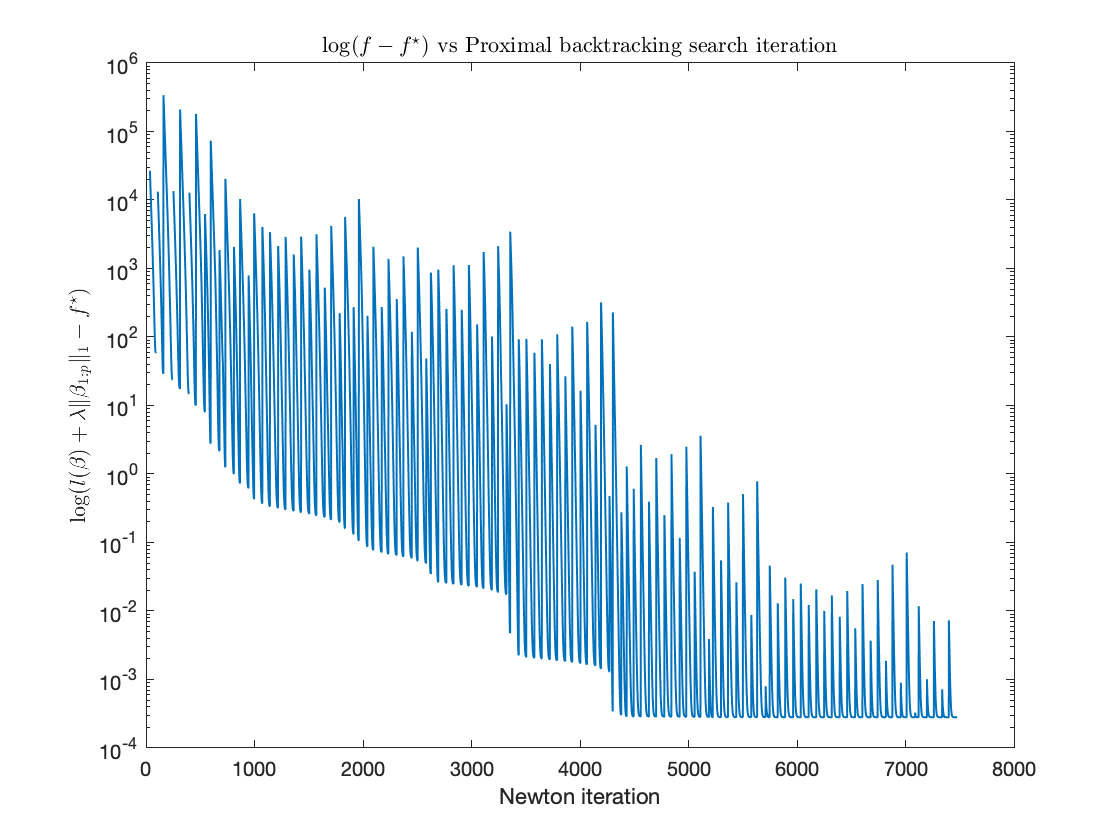

% Proximal update
[beta_prox, obj_list_prox] = proximal_lasso(x_train,y_train,lambda,step_beta,TOL);
semilogy(obj_list_prox-f_star, 'LineWidth', 1);
xlabel('Newton iteration');
ylabel('$\log(l(\beta)+\lambda\|\beta_{1:p}\|_1-f^\star)$', 'Interpreter', 'latex');
title('$\log(f-f^\star)$ vs Proximal backtracking search iteration', 'Interpreter', 'latex');

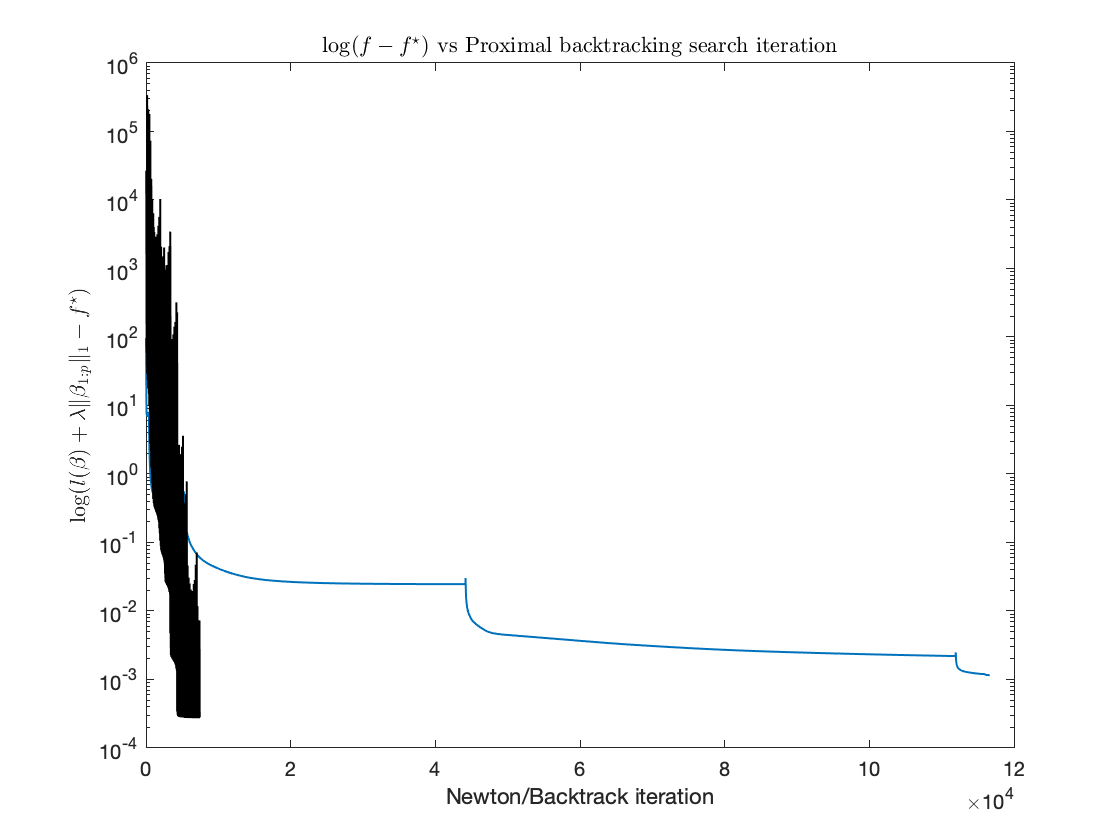

load('barrier.mat')
semilogy(obj_list-f_star, 'LineWidth', 1);
hold on;
semilogy(obj_list_prox-f_star, 'LineWidth', 1, 'Color', 'black');
xlabel('Newton/Backtrack iteration');
ylabel('$\log(l(\beta)+\lambda\|\beta_{1:p}\|_1-f^\star)$', 'Interpreter', 'latex');
title('$\log(f-f^\star)$ vs Proximal backtracking search iteration', 'Interpreter', 'latex')